## fv0 Intro

This scrip import expomential fitness as experiment data, and simulation result comes from PDE model with Reflecting boundaries |x|<=a.

This scrip just changing para by hand and make the frame of simulation.

## fv1 Intro

In this scrip, we try to adjust para automatically. First we use **gradient descent**. 

## fv5 Intro

In this scrip, we adapt GD into steepest descent.

## GLENII fv2

change FDE into GLENII

## Import data and previewing

The data come from expomential fitness data.

data_name='n142';
selecting_curve='xy';
data_mode="mixed data";%data mode is "processed data" or "mixed data"
Selecting_Mode='discard'; %'discard','average'
if data_mode=="processed data"
    experiment_interval=30;
    min_length=40;
    time_scale=experiment_interval*(1:min_length);
    
    load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\processed data ',data_name,'_',num2str(experiment_interval),'s.mat'])
    
    fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
    t=time_scale;
    a(1)=2.542e+05;%n142_30s
    a(2)=9.705e-05;
    a(3)=-1.391e+05;
    a(4)=-0.01086;
    
    Reserved_length=min_length;
    interceptive_experiment_MSD=[time_scale;1e-18*fun(a,time_scale)];
elseif data_mode=="mixed data"
    interceptive_experiment_MSD=[];
    load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\mixed data ',data_name,' ', Selecting_Mode,'.mat'])
    for i=1:length(t_mixMSD(1,:))
        if t_mixMSD(1,i)<=1200
            interceptive_experiment_MSD=[interceptive_experiment_MSD,[t_mixMSD(1,i);1e-18*t_mixMSD(2,i)]];
        end
    end
end


## Parameter importing

kB=1.3806505e-23;
T=293;%confirmed

input=[2.59727626912960e-08,	2.99863601406629e-07,	0.697075083079253];
mpsi=input(1);%m
zeta=input(2);
H=input(3);

% decide step length and sample length (proportional)

step_length=1/100;
sample_length=1/100000;

## storage system

% add parameter history and gradient history
parameter_history=[mpsi,zeta,H];
gradient_history=[];
residual_history=[];

## Main loop

for step_number=1:200
    residual_0=GLENII_get_residual(interceptive_experiment_MSD,mpsi,zeta,H);
    residual_mspi=GLENII_get_residual(interceptive_experiment_MSD,mpsi*(1+sample_length),zeta,H);
    residual_zeta=GLENII_get_residual(interceptive_experiment_MSD,mpsi,zeta*(1+sample_length),H);
    residual_H=GLENII_get_residual(interceptive_experiment_MSD,mpsi,zeta,H*(1+sample_length));
    gradient=[residual_mspi-residual_0,residual_zeta-residual_0,residual_H-residual_0]/sample_length;
    unit_gradient=gradient/norm(gradient);
    if step_number==1
        standard_gradient=norm(gradient);
    end
    
    %por=norm(gradient)/standard_gradient;
    por=residual_0/norm(gradient);
    mpsi=mpsi*(1-unit_gradient(1)*step_length*por);
    zeta=zeta*(1-unit_gradient(2)*step_length*por);
    H=H*(1-unit_gradient(3)*step_length*por);
    
    parameter_history=[parameter_history;[mpsi,zeta,H]];
    gradient_history=[gradient_history;gradient];
    residual_history=[residual_history;residual_0];
end

## saving

saving data

%saving_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.02图像';
%save([saving_location,'\data\history data N=',num2str(Total_experiment_number),' step=',num2str(step_length),datestr(now,' yyyy-mm-dd HH'),'.mat'],'parameter_history','gradient_history','residual_history')

Plot and plot saving: gradient history

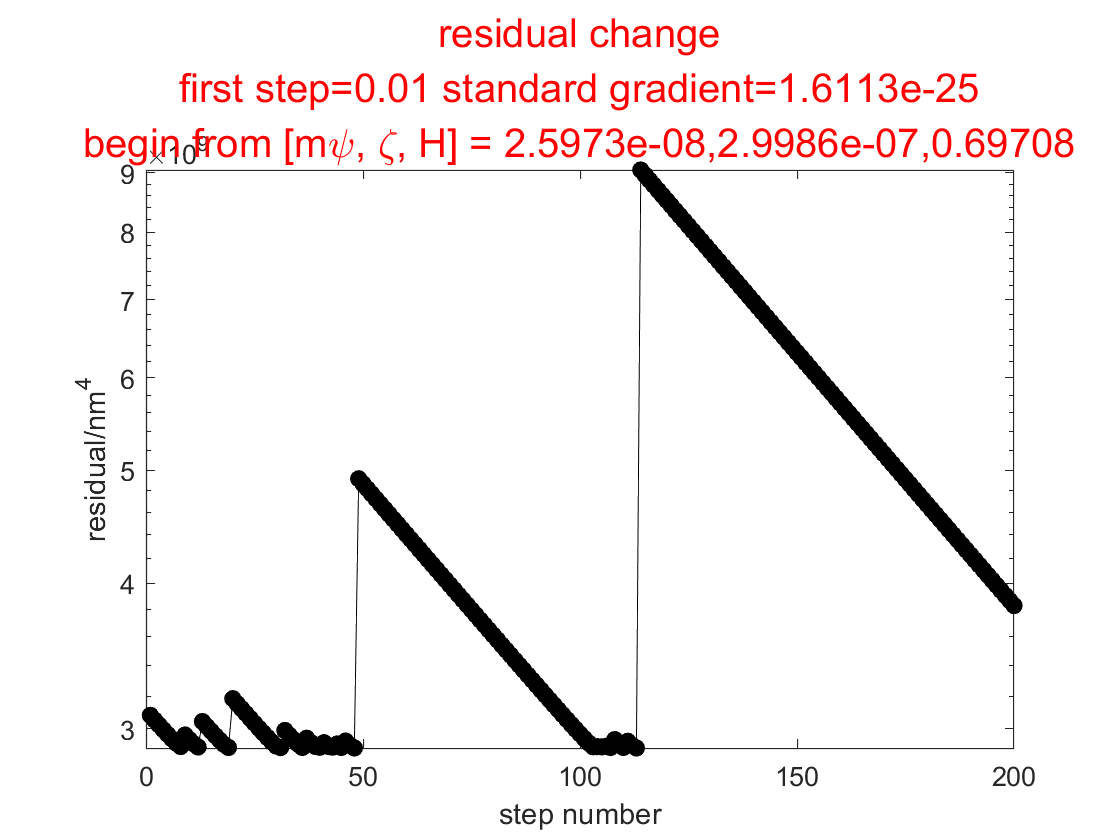

figure
plot((residual_history(:,1))*1e36,'k-o','MarkerFaceColor','k')
xlabel('step number')
ylabel('residual/nm^4')
set(gca,'yscale','log');
title({'residual change',['first step=',num2str(step_length),' standard gradient=',num2str(standard_gradient)],['begin from [m\psi, \zeta, H] = ',num2str(input(1)),',',num2str(input(2)),',',num2str(input(3))]},'Color','r','FontSize',15)

plot MSD

[min_residual,min_point]=min(residual_history)

min_residual = 2.8891e-27

min_point = 113


mpsi=parameter_history(min_point,1);%m
zeta=parameter_history(min_point,2);
H=parameter_history(min_point,3);


simulation_MSD=[];
tau=((zeta*gamma(2*H+1))/mpsi)^(1/(2-2*H));
for t=interceptive_experiment_MSD(1,:)
    simulation_MSD=[simulation_MSD,2*kB*T/mpsi-2*kB*T/mpsi*mlf(2-2*H,1,-(t/tau)^(2-2*H),8)];
end
residual=sum((interceptive_experiment_MSD(2,:)-simulation_MSD).^2);

Plot and saving

figure
hold on
plot(interceptive_experiment_MSD(1,:),interceptive_experiment_MSD(2,:),'+',"LineWidth",2,'displayname','expomential fitness data')
%plot(time_scale,1e-18*processed_MSD(1:min_length),'+',"DisplayName",'experiment xy average data',"Color",'cyan',"LineWidth",1)
legend_name=strcat('GLENII simulation MSD',' m*\psi= ',num2str(mpsi),'m \zeta=',num2str(zeta),' H= ',num2str(H));
plot(sort(interceptive_experiment_MSD(1,:)),sort(simulation_MSD),"LineWidth",2,'displayname',legend_name)
xlabel('t  /  s','FontSize',14);
ylabel('MSD / m^2','FontSize',14);
title({['processed experiment MSD & GLENII simulation MSD -t'],['processed experiment data: ',strrep(data_name,'_','\_'),'\_',selecting_curve],['residual = ',num2str(residual),'m^4']},'Color','r','FontSize',10);
legend('Location','southoutside');

Saving

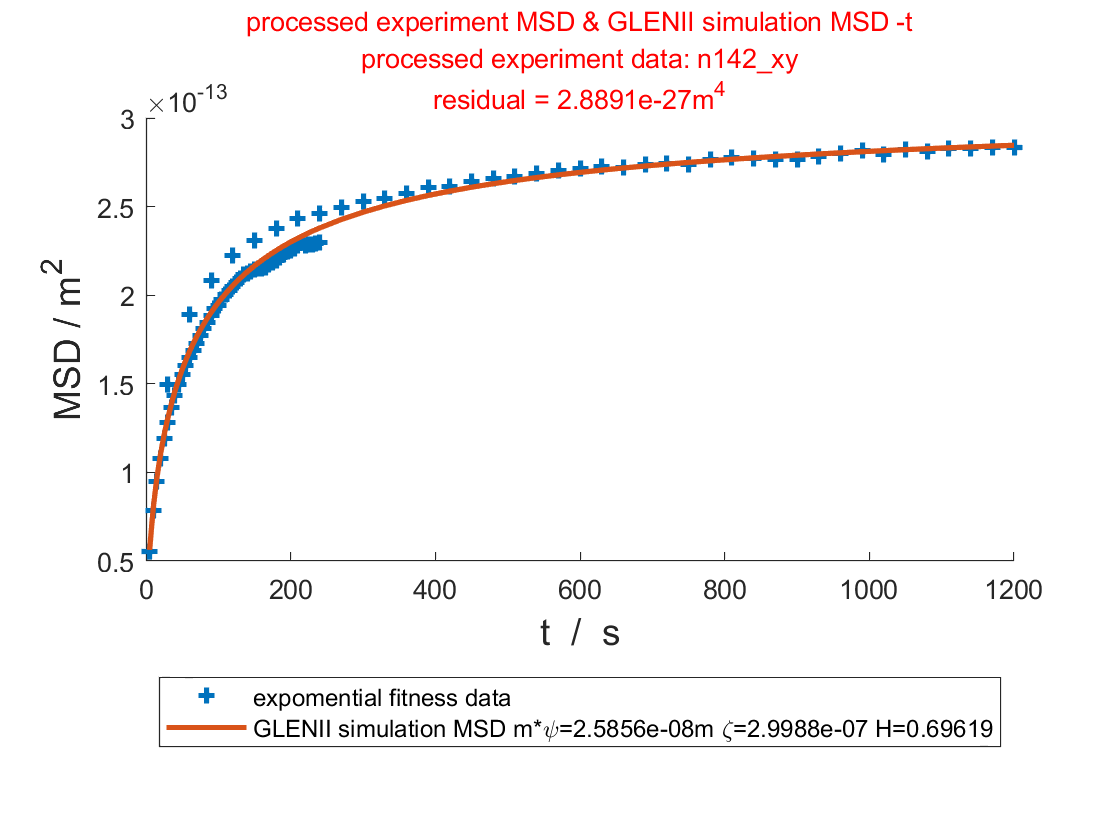

storage_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.05图像';
c=clock;
saveas(gcf,strrep([storage_location,'\image\GLE-MSD ',data_name,'_',num2str(experiment_interval),'s ',num2str(c(1)),'.',num2str(c(2)),'.',num2str(c(3)),' ',num2str(c(4)),num2str(c(5)),'.jpg'],'       ',' '))

disp para

vpa_length=5;
disp([(num2str(double(vpa(mpsi,vpa_length)))),'|',(num2str(double(vpa(zeta,vpa_length)))),'|',(num2str(double(vpa(H,vpa_length)))),'|',num2str(double(vpa(min_residual,vpa_length)))])

2.5856e-08|2.9988e-07|0.69619|2.8891e-27
